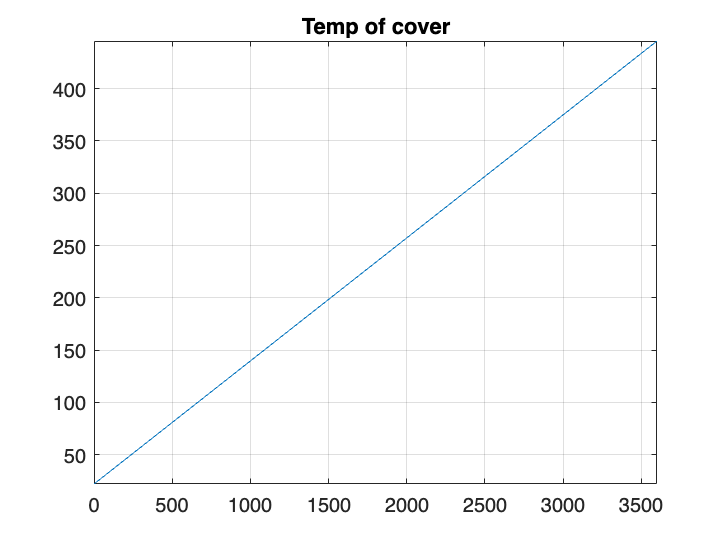

% % Import Weather file from csv
T = readtable('/Users/elliecarey/Desktop/EngDes/Year 4/Design Project 4/Models/Bristol_weather_matlab.csv','PreserveVariableNames',true);
% T_air = T{: ,"Dry Bulb"}';
% T_amb = T_air/10;
% T_amb = [10.4,9.7,9.9,9.9,9.5,9.7,9.3,9.3,9.2,8.8]
% T_sky = zeros(1,length(T_amb));
% 
% for i = 1:length(T_amb)
%     T_sky(i) = 273 + 0.0552*(T_amb(i)^1.5); % Sky Temperature
% end
% T_sky


% Time = T{:, "Var1"}';
% plot(Time, T_air)

% Constants
T_a = 22; % Ambient Air Temperature
T_sky = 0.0552*((T_a)^1.5)+273; % Sky Temperature
T_c = 22; % Temperature of cover 
T_s = 22; % Temperature of soil 
T_i = 22; % Inside air temperature 
T_s1 = 22; % Sub-soil layer 1 temperature
T_s2 = 22; % Sub-soil layer 2 temperature 
I = 40; % Incident solar radiation
sigma = 0.00000005670374419; % Stefan-Boltzmann constant 
c_pa = 1005; % Ambient specific heat 
c_pc = 750; % Cover specific heat 
c_ps = 1900; % Soil specific heat
H = 3; % Back height of greenhouse
z_0 = 0.01; % Soil depth (1cm)
z_1 = 0.1; % Soil depth (10cm)
z_2 = 0.1; % Soil depth (20cm)
z_3 = 0.3; % Soil depth (50cm)
density_a = 1.2; % Density of air 
density_c = 2800; % Density of cover
density_s = 1500; % Density of soil 
b = 0.004; % Cover thickness (m)
k_s = 1; % Thermal conductivity of soil (W/mK)
N = 1; % Number of air changes per hour (ach)
S_c = 29.2; % Surface area of cover (m^2)
S_s = 7.6; % Surface area of soil (m^2)
alpha_c = 0.1; % Cover absorptivity of solar radiation 
alpha_ct = 0.95; % Cover absorptivity of thermal radiation 
alpha_s = 0.86; % Soil absorptivity of solar radiation 
alpha_st = 1; % Soil absorptivity of thermal radiation 
E_c = 0.9; % Emissivity of cover 
E_s = 0.93; % Emissivity of soil
E_sky = 0.8; % Emissivity of sky
tau_c = 0.85; % Cover transmittance 
V_w = 6.3; % Wind velocity (m/s)
h_coca = 0.95 + 6.76*(V_w)^0.49; % Convection heat transfer coefficient (cover to ambient)

h_coic = 1.95*((T_c - T_i)^0.3); % Convection heat transfer coefficient (inside to cover)
h_cosi = 1.52*((T_s - T_i)^0.33); % Convection heat transfer coefficient (soil to inside)
q_sc = alpha_c*I*(1+tau_c*(1-alpha_c)); % Solar radiation absorbed by cover (W/m^2)
q_ss = alpha_s*tau_c*I; % Solar radiation absorbed by soil (W/m^2)
q_rcnet = (-E_c*sigma*((T_c)^4)*S_c + alpha_ct*E_sky*sigma*((T_sky)^4)*S_c + alpha_ct*E_s*sigma*((T_s)^4)*S_s)*(1/S_s); % Net thermal radiation rate of cover (W/m^2)
q_rsnet = (-E_s*sigma*((T_s)^4)*S_s + alpha_st*E_c*sigma*((T_c)^4)*S_c)*(1/S_s); % Net thermal radiation rate of soil (W/m^2)
q_inf = density_a*c_pa*N*H*((T_i - T_a)/3600); % Infiltration heat trasnfer rate (W/m^2)
q_coca = h_coca*(T_c - T_a); % Convection heat transfer rate (cover to ambient)
q_coic = h_coic*(T_i - T_c); % Convection heat transfer rate (inside to cover)
q_cosi = h_cosi*(T_s - T_i); % Convection heat transfer rate (soil to inside)
q_k = (k_s*(T_s-T_s1))/z_1; % Conduction heat trasnfer rate 

syms T_c(t) T_i(t) T_s(t) T_s1(t) T_s2(t)
ode1 = diff(T_c) == (7.06 + q_rcnet + q_coic - h_coca)/(8400);
ode2 = diff(T_i) == (q_cosi + q_inf - q_coca)/(3618);
ode3 = diff(T_s) == (29.24 - q_cosi - q_k - q_rsnet)/(15075);
ode4 = diff(T_s1) == ((T_s-T_s1)/0.1 - (T_s1-T_s2)/0.1)/(285000);
ode5 = diff(T_s2) == ((T_s1-T_s2/0.1 - (T_s2-T_s)/0.3))/(285000);
odes = [ode1; ode2; ode3; ode4; ode5];

% T_a = T_amb
cond1 = T_c(0) == T_a;
cond2 = T_i(0) == T_a;
cond3 = T_s(0) == T_a;
cond4 = T_s1(0) == T_a;
cond5 = T_s2(0) == T_a;
conds = [cond1; cond2; cond3; cond4; cond5];

[T_cSol(t),T_iSol(t),T_sSol(t),T_s1Sol(t),T_s2Sol(t)] = dsolve(odes,conds);

fplot(T_cSol, [0 3600])
title('Temp of cover')
grid on

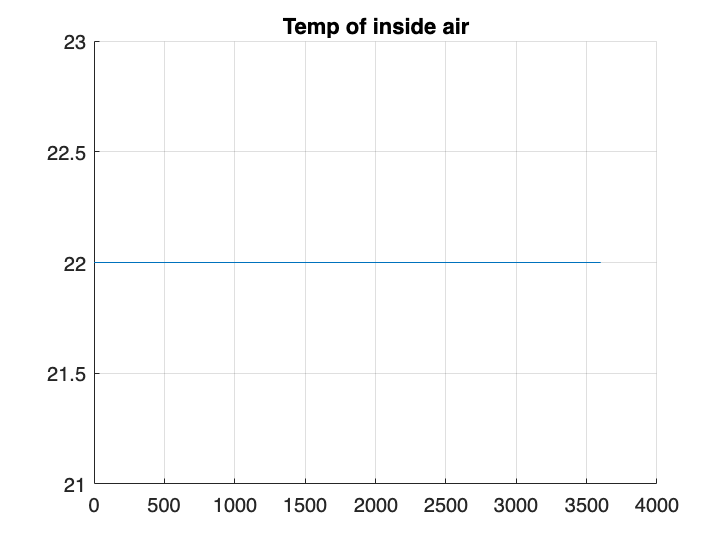

figure
hold on
fplot(T_iSol,  [0 3600])
title('Temp of inside air')
grid on

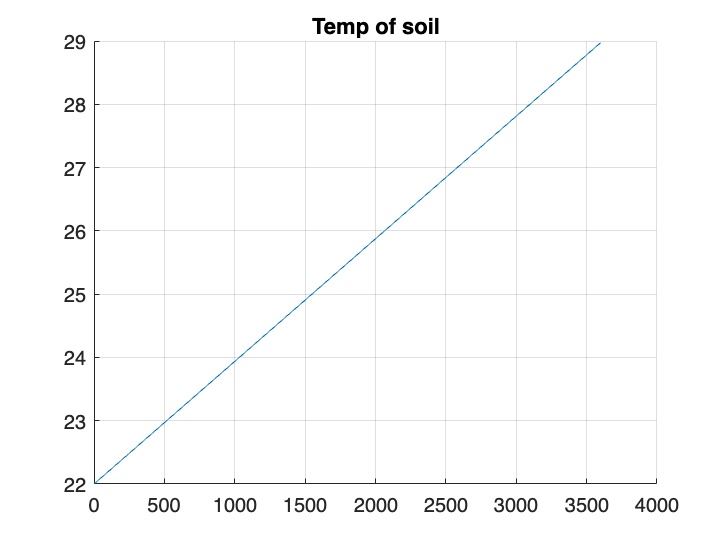

figure
hold on 
fplot(T_sSol,  [0 3600])
title('Temp of soil')
grid on

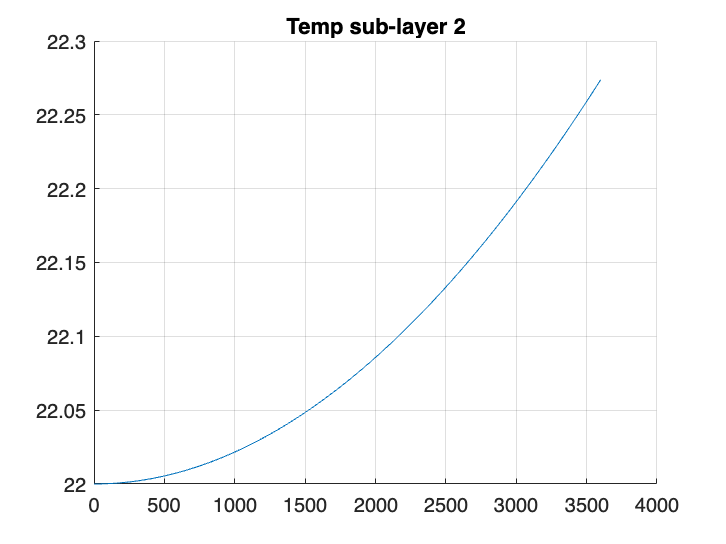

figure
hold on 
fplot(T_s1Sol,  [0 3600])
title('Temp sub-layer 2')
grid on

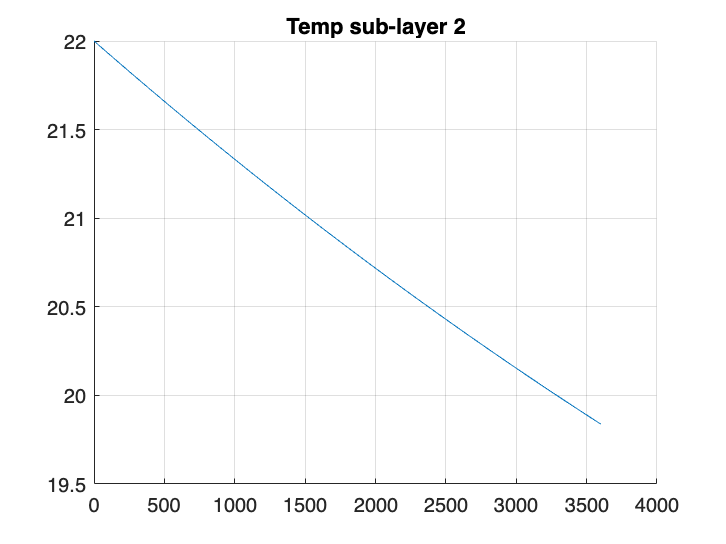

figure
hold on 
fplot(T_s2Sol,  [0 3600])
title('Temp sub-layer 2')
grid on

% % legend('T_cSol','T_iSol', 'T_sSol','T_s1Sol','T_s2Sol')